# Homework 3

## Created by Wei Ye

## Date: June 21, 2022

## Due on June 22, 23:59

### Question 1

Please see the attached code in 'census_data_analysis_hw.m' in the email.

I checked my new file on June 21, it worked. The main change i did is adding additional data into my original data set x in which i don't need to combine data anymore. 

### Question 2

y_obs=[7 3.5 3 1.75 1.25 0.2 -1.2];
y_pred=my_linear_eq(6,-1,y_obs)

y_pred =     9.0000    7.1667    5.3333    3.5000    1.6667   -0.1667   -2.0000


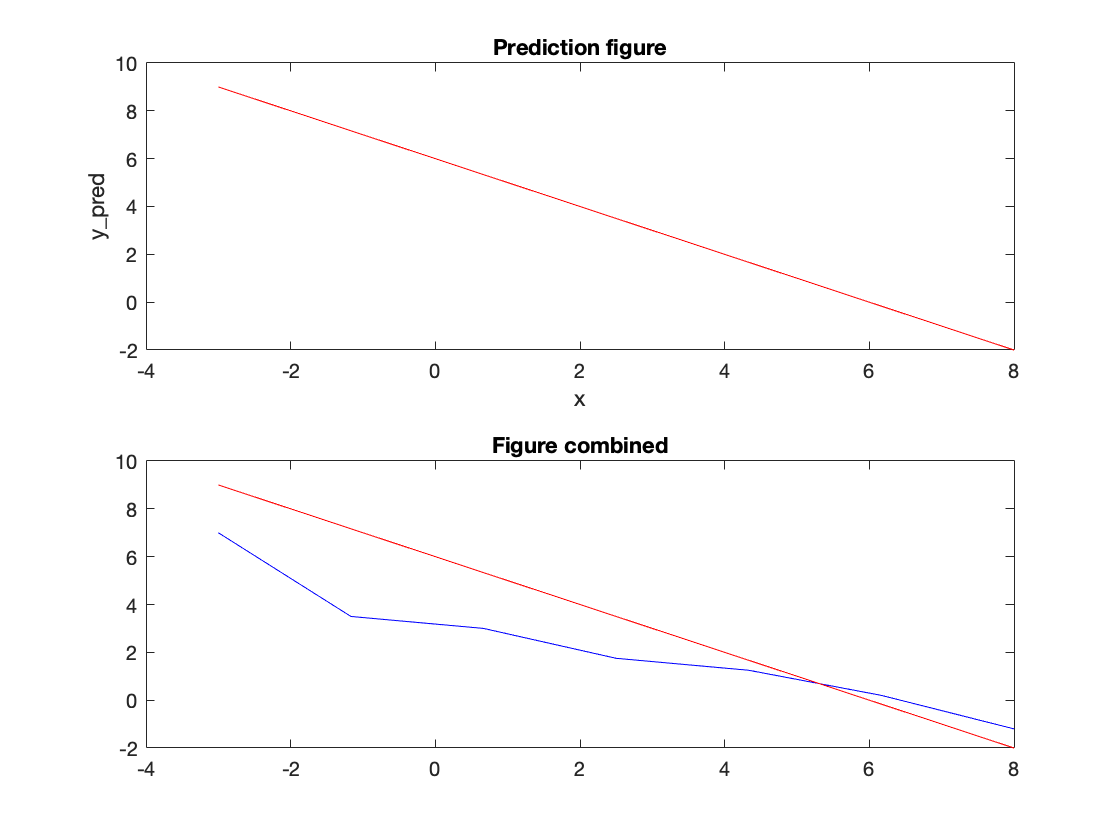

x=linspace(-3,8,size(y_obs,2));
subplot(2,1,1);
plot(x,y_pred,"r")
title('Prediction figure')
xlabel('x')
ylabel("y\_pred")
subplot(2,1,2);
plot(x,y_obs,"b-");
hold on
plot(x,y_pred,"r")
title('Figure combined')

square_errors=(y_pred-y_obs).^2;
sse_total=sum(square_errors);
MSE=mean(sse_total)

MSE = 26.8994

No, it's not a good fit. 

Obvious if we increase the slope, it can fitt the data better (As the the slop is negative), for example, change a=5,b=-0.7

y_pred1=my_linear_eq(5,-0.7,y_obs);
MSE1=mean(sum((y_pred1-y_obs).^2))

MSE1 = 11.0853

It decreases! Since our data is limited, it's very easy to overfit. But in this case, we know we can change the MSE if we change parameters.